# Industrial Robotics : Robotic Leg

Authors: 

clear; close all; clc;

## Direct Kinematics

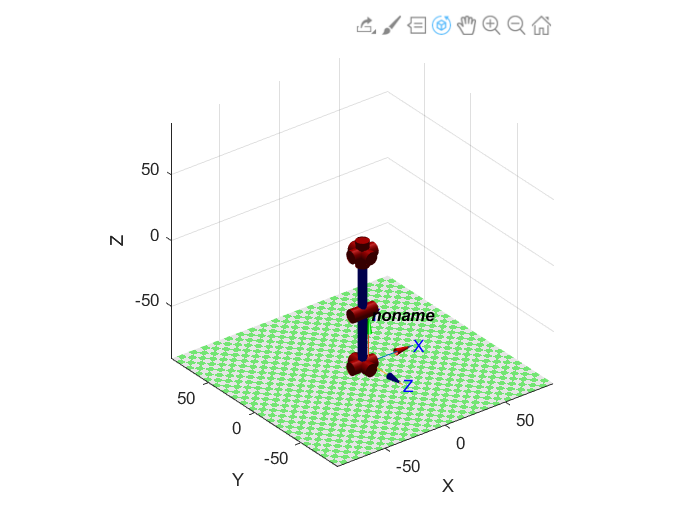

syms a f d t a3 a4 a5 a6 d3 t1 t2 t3 t4 t5 t6 real

A = [cos(t) -sin(t)*cos(f) sin(t)*sin(f) a*cos(t);
     sin(t) cos(t)*cos(f) -cos(t)*sin(f) a*sin(t);
       0       sin(f)         cos(f)        d;
       0         0              0           1];

a3 = 40; % length of thigh
a4 = 35; % length of the lower leg
a6 = 5; %distance between ankle joint and feet 
  

%Devanit-Hartenberg 

DH_Hip = [0 0 a4 0];


%the first one is just to check if the joints are all in the right
%orientation
DH_Leg = [0 0 a3    pi/2; %a5 just to show -change to 0 
          pi/2 0  a3 -pi/2 ; %a5/3 same change to 0
          0  0  a3   pi/2;  %a3 is the thigh length
          0  0  a4   -pi/2;  %a4 is the lower leg length
          0  0  a5 pi/2; %a5/5 same change to 0
          90 0  a6   -pi/2]; %a6 is the feet 
      
DH_Leg = [0 0  0    pi/2; %a5 just to show -change to 0 
          pi/2 0  0  -pi/2; %a5/3 same change to 0
          0  0  a3      0;  %a3 is the thigh length
          0  0  a4      0;  %a4 is the lower leg length
          0  0  0    pi/2; %a5/5 same change to 0
          0 0  a6      0]; %a6 is the feet 
 
%other way 
%L1=Link('d',0,'a',0,'alpha',pi/2);
%L2=Link('d',0,'a',0,'alpha',pi/2,'theta',90);
%L3=Link('d',0 'a',a3,'alpha',pi/2);
%L4=Link('d',0,'a',a4,'alpha',pi/2);
%L5=Link('d',0,'a',0,'alpha',pi/2); 
%L6=Link('d',0,'a',a5,'alpha',pi/2,'theta',90);
%Rob1 = SerialLink([L1 L2 L3 L4 L5 L6], 'name', 'Robotic Leg');
  
% Base frame
Tb0 = [1   0   0   0;
       0  -1   0   0;
       0   0  -1   0; %normaly P_z = leg legth   
       0   0   0   1];

% Structure generation and plot
%Rob = SerialLink([l1 l2 l3 l4 l5 l6],'name','Rob');
%Rob = SerialLink([DH_Hip; DH_Leg]);
Rob_Leg = SerialLink(DH_Leg);
Rob.base = Tb0;
%Rob.plot([0 pi/2 pi/2 0 0 0 pi/2]);
Rob_Leg.plot([0 -pi/2 0 0 0 pi/2]);


n=size(DH_Leg,1);  %Number of joints

% Intermediate transformation Matrices
for i=1:n
    eval("A"+int2str(i)+int2str(i-1)+"=subs(A,[t d a f],DH_Leg(i,:));");
end
% Multiplication of all the A_i^i-1 and extraction of the z_i-1 e p_i-1
z0 = [0;0;1];
p0 = [0;0;0];
z1 = A10(1:3,1:3)*z0;
p1 = A10(1:3,2:4)*z0;
eval("T"+int2str(n)+"0=A10;");
for i=2:n
    eval("T"+int2str(n)+"0=T"+int2str(n)+"0*A"+int2str(i)+int2str(i-1)+';');
    eval("z"+int2str(i)+"=T"+int2str(n)+"0(1:3,1:3)*z0;");
    eval("p"+int2str(i)+"=T"+int2str(n)+"0(1:3,2:4)*z0;");
end

eval("T"+int2str(n)+"0s=simplify(T"+int2str(n)+"0)");

$$T60s = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 90\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Inverse Differential Kinematics 

% Geometric jacobian
J = Rob_Leg.jacobe(([0 -pi/2 0 pi/4 0 pi/2]))

J =   -28.2843   73.2843    0.0000    0.0000         0         0
   -3.5355    3.5355  -31.8198         0    0.0000    5.0000
   -3.5355   -3.5355  -71.8198  -40.0000   -0.0000         0
    0.0000   -0.0000    1.0000    1.0000    1.0000         0
    0.7071    0.7071    0.0000    0.0000    0.0000         0
   -0.7071    0.7071    0.0000    0.0000    0.0000    1.0000


Rank = rank(J)

Rank = 6

% under assumption of rotary joints only
for i=1:n
    eval("J = [J , [cross(z"+int2str(i-1)+",(p"+int2str(n)+"-p"+int2str(i-1)+")) ; z"+int2str(i-1)+"]];");
end
J = simplify(J);

%simplify(det(J))

syms n_x n_y n_z s_x s_y s_z a_x a_y a_z p_x p_y p_z 
%decoupling the system into postition and orientation subsystems 
% view the the Inverse Differential Kinematics Probelm in reverse so that the postion of
%the "hip" - p_hip is a function of the other joints (4,5 and 6) 
%IK in reserve way T' = [ n s a p_d; 0 0 0 1 ]^-1 = [n' s' a' p_d'; 0 0 0 1]
n = [n_x; n_y; n_z]

$$n = \left(\begin{array}{c} n_{x}\\ n_{y}\\ n_{z} \end{array}\right)$$

s = [s_x; s_y; s_z]

$$s = \left(\begin{array}{c} s_{x}\\ s_{y}\\ s_{z} \end{array}\right)$$

a = [a_x; a_y; a_z]

$$a = \left(\begin{array}{c} a_{x}\\ a_{y}\\ a_{z} \end{array}\right)$$

p_d = [p_x; p_y; p_z]

$$p\_d = \left(\begin{array}{c} p_{x}\\ p_{y}\\ p_{z} \end{array}\right)$$

% ...
c4 = ((p_x' + a6)^2 + p_y'^2 + p_z'^2 -a3^2-a4^2)/(2*a3*a4)

$$c4 = \frac{{\bar{p_{y}}}^{2}}{3600}+\frac{{\bar{p_{z}}}^{2}}{3600}+\frac{{\left(\bar{p_{x}}+5\right)}^{2}}{3600}-\frac{145}{144}$$

s4 = sqrt(1-c4^2)

$$s4 = \sqrt{1-{\left(\frac{{\bar{p_{y}}}^{2}}{3600}+\frac{{\bar{p_{z}}}^{2}}{3600}+\frac{{\left(\bar{p_{x}}+5\right)}^{2}}{3600}-\frac{145}{144}\right)}^{2}}$$

theta4 = atan2(s4,c4) %+- before s4

$$theta4 = \text{atan2}\left(\sqrt{1-{\left(\frac{{\bar{p_{y}}}^{2}}{3600}+\frac{{\bar{p_{z}}}^{2}}{3600}+\frac{{\left(\bar{p_{x}}+5\right)}^{2}}{3600}-\frac{145}{144}\right)}^{2}},\frac{{\bar{p_{y}}}^{2}}{3600}+\frac{{\bar{p_{z}}}^{2}}{3600}+\frac{{\left(\bar{p_{x}}+5\right)}^{2}}{3600}-\frac{145}{144}\right)$$

theta6 = atan2(p_y',-p_x'-a5)

$$theta6 = \text{atan2}\left(\bar{p_{y}},-a_{5}-\bar{p_{x}}\right)$$

theta5 = atan2(-p_z', sqrt((p_x' + a6)^2 + p_y'^2)) - atan2(s4*a3,c4*a3+a4) %+- before the sqrt

$$theta5 = \begin{array}{l} -\text{atan2}\left(45\,\sqrt{1-{\left(\frac{{\bar{p_{y}}}^{2}}{3600}+\frac{{\bar{p_{z}}}^{2}}{3600}+\frac{\sigma_{1}}{3600}-\frac{145}{144}\right)}^{2}},\frac{{\bar{p_{y}}}^{2}}{80}+\frac{{\bar{p_{z}}}^{2}}{80}+\frac{\sigma_{1}}{80}-\frac{85}{16}\right)+\text{atan2}\left(-\bar{p_{z}},\sqrt{{\bar{p_{y}}}^{2}+\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\bar{p_{x}}+5\right)}^{2} \end{array}$$

%if cos(theta4+theta5)*a3 + cos(theta5)*a4 < 0
%  theta6 = theta6 + pi;
%end
s6 = sin(theta6);
c6 = cos(theta6);
theta3 = atan2(a_z', c6*a_x' - s6*a_y') - theta4 -theta5

$$theta3 = \begin{array}{l} \text{atan2}\left(45\,\sigma_{2},\frac{{\bar{p_{y}}}^{2}}{80}+\frac{{\bar{p_{z}}}^{2}}{80}+\frac{\sigma_{4}}{80}-\frac{85}{16}\right)-\text{atan2}\left(\sigma_{2},\sigma_{3}\right)-\text{atan2}\left(-\bar{p_{z}},\sqrt{{\bar{p_{y}}}^{2}+\sigma_{4}}\right)+\text{angle}\left(\bar{a_{z}}\,\mathrm{i}-\frac{\bar{a_{x}}\,\left(a_{5}-\mathrm{imag}\left(p_{y}\right)+\mathrm{real}\left(p_{x}\right)\right)}{\sigma_{1}}-\frac{\bar{a_{y}}\,\left(\mathrm{imag}\left(p_{x}\right)+\mathrm{real}\left(p_{y}\right)\right)}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\left|a_{5}+\bar{p_{x}}-\bar{p_{y}}\,\mathrm{i}\right|\\ \sigma_{2}=\sqrt{1-{\sigma_{3}}^{2}}\\ \sigma_{3}=\frac{{\bar{p_{y}}}^{2}}{3600}+\frac{{\bar{p_{z}}}^{2}}{3600}+\frac{\sigma_{4}}{3600}-\frac{145}{144}\\ \sigma_{4}={\left(\bar{p_{x}}+5\right)}^{2} \end{array}$$

theta2 = atan2(sqrt(1- (s6*a_x'+ c6*a_y')),s6*a_x'+c6*a_y') %+- before the sqrt

$$theta2 = \begin{array}{l} \text{angle}\left(\sqrt{\sigma_{1}-\sigma_{2}+1}\,\mathrm{i}-\sigma_{1}+\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\bar{a_{y}}\,\left(a_{5}-\mathrm{imag}\left(p_{y}\right)+\mathrm{real}\left(p_{x}\right)\right)}{\left|a_{5}+\bar{p_{x}}-\bar{p_{y}}\,\mathrm{i}\right|}\\ \sigma_{2}=\frac{\bar{a_{x}}\,\left(\mathrm{imag}\left(p_{x}\right)+\mathrm{real}\left(p_{y}\right)\right)}{\left|a_{5}+\bar{p_{x}}-\bar{p_{y}}\,\mathrm{i}\right|} \end{array}$$

theta1 = atan2(-s6*s_x' - c6*s_y', -s6*n_x' -c6*n_y')

$$theta1 = \begin{array}{l} \text{angle}\left(\frac{\bar{n_{y}}\,\left(a_{5}-\mathrm{imag}\left(p_{y}\right)+\mathrm{real}\left(p_{x}\right)\right)}{\sigma_{1}}+\frac{\bar{s_{y}}\,\left(a_{5}-\mathrm{imag}\left(p_{y}\right)+\mathrm{real}\left(p_{x}\right)\right)\,\mathrm{i}}{\sigma_{1}}-\frac{\bar{n_{x}}\,\left(\mathrm{imag}\left(p_{x}\right)+\mathrm{real}\left(p_{y}\right)\right)}{\sigma_{1}}-\frac{\bar{s_{x}}\,\left(\mathrm{imag}\left(p_{x}\right)+\mathrm{real}\left(p_{y}\right)\right)\,\mathrm{i}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\left|a_{5}+\bar{p_{x}}-\bar{p_{y}}\,\mathrm{i}\right| \end{array}$$

s2 = sin(theta2);
%if s2 < 0 
% theta1 = theta1 + pi;
% theta3 = theta3 + pi;
%end

%todo


## Robot simulation

Animate: saving video --> test2.mp4 with profile 'MPEG-4'


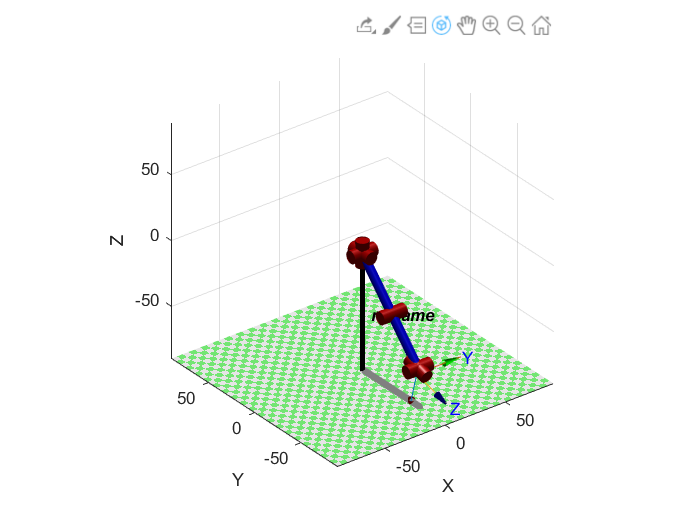

% Parameters setting

t1= zeros(1,101);
t2= -pi/2+ zeros(1,101);
t3= -[-pi/4:2*pi/400:pi/4];
t4= -[[-pi/2:pi/100:0],zeros(1,50)];
t5= pi/3* ones(1,101);
t6= zeros(1,101);

Q=[t1;t2;t3;t4;t5;t6];

% Links generation (under assumption of rotary joints only)
%for i=1:n
%    eval("l"+int2str(i)+"=Link('a',"+int2str(eval(DH_Leg(i,1)))+",'alpha',"+int2str(eval(DH_Leg(i,2)))+",'d',"+int2str(eval(DH_Leg(i,3)))+");");
%end
% Structure generation and plot
%Rob = SerialLink([l1 l2 l3 l4 l5 l6],'name','Rob');
%Rob.base = Tb0;
Rob_Leg.plot(Q','fps',30,'movie','test2.mp4');